clc
clear
close all;

data=load('100.csv');
data=data(1:30000)'

data =    -0.0126   -0.0109   -0.0085   -0.0051   -0.0005    0.0051    0.0109    0.0164    0.0209    0.0238    0.0249    0.0244    0.0229    0.0209    0.0191    0.0182    0.0184    0.0203    0.0239    0.0295    0.0368    0.0455    0.0547    0.0630    0.0689    0.0707    0.0677    0.0599    0.0483    0.0345    0.0208    0.0089    0.0002   -0.0048   -0.0064   -0.0054   -0.0033   -0.0014   -0.0011   -0.0031   -0.0073   -0.0132   -0.0197   -0.0258   -0.0307   -0.0337   -0.0350   -0.0350   -0.0344   -0.0342


fs = 360;


time = (0:length(data)-1)/fs;

f = 2;                                          

x=data

x =    -0.0126   -0.0109   -0.0085   -0.0051   -0.0005    0.0051    0.0109    0.0164    0.0209    0.0238    0.0249    0.0244    0.0229    0.0209    0.0191    0.0182    0.0184    0.0203    0.0239    0.0295    0.0368    0.0455    0.0547    0.0630    0.0689    0.0707    0.0677    0.0599    0.0483    0.0345    0.0208    0.0089    0.0002   -0.0048   -0.0064   -0.0054   -0.0033   -0.0014   -0.0011   -0.0031   -0.0073   -0.0132   -0.0197   -0.0258   -0.0307   -0.0337   -0.0350   -0.0350   -0.0344   -0.0342


peaks = PeakDetection(data,f/fs);                  % peak detection

   1

    1.0291

    0.3745

   1

  Columns 1 through 30

     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30

  Columns 31 through 60

    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60

  Columns 61 through 90

    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90

  Columns 91 through 120

    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120

  Columns 121 through 150

   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138 


[phase, phasepos] = PhaseCalculation(peaks);     % phase calculation

teta = 0;                                       % desired phase shift
pphase = PhaseShifting(phase,teta);             % phase shifting

bins = fs/2;                                     % number of phase bins
[ECGmean,ECGsd,meanphase] = MeanECGExtraction(x,pphase,bins,1); % mean ECG extraction 

India =    224   225


mean_test = -0.0146

std_test = 0.0013

mean_mid =    -0.0146   -0.0168   -0.0173   -0.0156   -0.0131   -0.0101   -0.0062   -0.0033   -0.0006    0.0019    0.0036    0.0040    0.0024   -0.0005   -0.0035   -0.0031    0.0011    0.0078    0.0151    0.0216    0.0224    0.0197    0.0140    0.0100    0.0074    0.0051    0.0035    0.0010   -0.0021   -0.0060   -0.0124   -0.0173   -0.0208   -0.0225   -0.0218   -0.0208   -0.0204   -0.0211   -0.0233   -0.0256   -0.0288   -0.0338   -0.0368   -0.0242   -0.0210   -0.0149   -0.0043    0.0042    0.0126    0.0236



OptimumParams = []    


OptimumParams =

     []



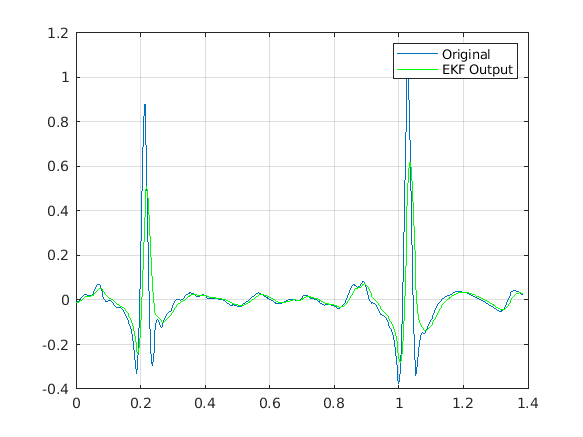



N = length(OptimumParams)/3;% number of Gaussian kernels
JJ = find(peaks);
fm = fs./diff(JJ);          % heart-rate
w = mean(2*pi*fm);          % average heart-rate in rads.
wsd = std(2*pi*fm,1);       % heart-rate standard deviation in rads.

y = [phase ; x];

X0 = [-pi 0]';
P0 = [(2*pi)^2 0 ;0 (10*max(abs(x))).^2];
Q = diag( [ (.5*OptimumParams(1:N)).^2 (.2*ones(1,N)).^2 (.2*ones(1,N)).^2 (wsd)^2 , (.2*mean(ECGsd(1:round(end/10))))^2] );
R = [(w/fs).^2/12 0 ;0 (mean(ECGsd(1:round(length(ECGsd)/10)))).^2];
Wmean = [OptimumParams w 0]';
Vmean = [0 0]';
Inits = [OptimumParams w fs];

InovWlen = ceil(.5*fs);     % innovations monitoring window length
tau = [];                   % Kalman filter forgetting time. tau=[] for no forgetting factor
gamma = 1;                  % observation covariance adaptation-rate. 0<gamma<1 and gamma=1 for no adaptation
RadaptWlen = ceil(fs/2);    % window length for observation covariance adaptation

% [Xekf,Phat]=UKF(X0,P0,Q,R,y,Wmean,Vmean);
[Xekf,Phat,Xeks,PSmoothed,ak] = EKSmoother(y,X0,P0,Q,R,Wmean,Vmean,Inits,InovWlen,tau,gamma,RadaptWlen,1);
Xekf = Xekf(2,:);

csvwrite('n100.csv',Xekf) 

% Graph print
% I = 1:length(x);
% t = (0:length(data)-1)/fs;
% figure
% plot(t,x);
% hold on;
% plot(t,Xekf','g');
% grid;
% legend('Original','EKF Output')



% % 